Requested 10000000000x1 (74.5GB) array exceeds maximum array size preference (16.0GB). This might cause MATLAB to become unresponsive.

Error in linspace (line 46)
        y = d1 + (0:n1).*(d2 - d1)./n1;

Related documentation

n = 200; % number of datapoints

p = 1 (one-dimension)

a = 0.1;
delta = sqrt( ...
    sqrt( 2 * (1+a) * log(n) ) ...
    );
mu_1 = -delta * 1

mu_1 = -1.8477

mu_2 =  delta * 1

mu_2 = 1.8477

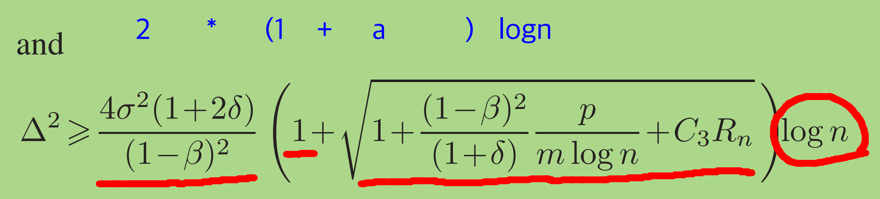\

**how to determine a?**

\

(p=1 i.e. univariate gaussian)

### Original method vs thresholding

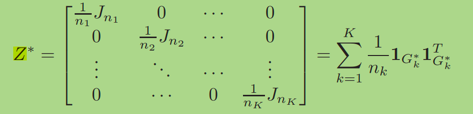

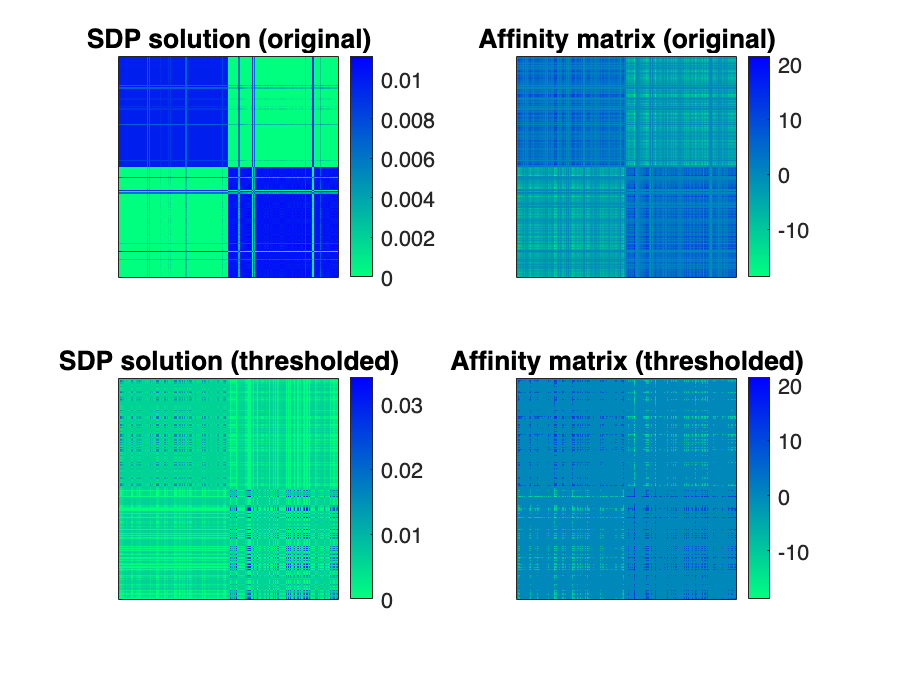

%data generation
x = [ ( mu_1+zeros(n/2, 1) ) ; ( mu_2 + zeros(n/2, 1) ) ] + randn(n, 1);

% original affinity matrix (or similarity matrix)
A = x * x';

%thresholded affinity matrix
thres = 7;
A_thres = A.*(abs(A)>thres);

% solve SDP problem (implemented in kmeans_sdp.m)
Z_org = kmeans_sdp(A, 2);
Z_thres = kmeans_sdp(A_thres, 2);

% takes about 15 seconds on this laptop


figure;

subplot(2,2,1)
imagesc(Z_org)
title('SDP solution (original)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,2)
imagesc(A)
title('Affinity matrix (original)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,3)
imagesc(Z_thres)
title('SDP solution (thresholded)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)
%
subplot(2,2,4)
%imagesc(abs(A))
imagesc(A_thres)
title('Affinity matrix (thresholded)')
colormap('winter')
colorbar
colormap(flipud(colormap));
set(gca,'xtick',[])
set(gca,'ytick',[])
axis equal
a=axis;
a(1)=a(3);
a(2)=a(4);
axis(a)


min(A.*(abs(A)>thres))

ans =    -7.3146         0  -15.4388  -13.2934  -10.6362   -8.0561         0   -9.9084         0         0         0   -7.9760  -11.6088  -15.4308   -7.8437         0   -9.9206  -11.0710   -9.9950  -13.6472  -10.8495   -9.4021   -8.3519   -8.8600         0   -8.0577         0   -7.1181         0  -11.9161         0   -9.7707         0         0  -18.6968  -14.7153  -15.2436         0         0  -10.0792         0         0  -13.4388         0  -12.0495         0   -8.7153         0  -10.5346         0
